%define constants

k_wall = .04; %W/m-K
%sa_wall = total surface area of wall in contact with internal air
sa_wall = (.2*5) + (5.1*5) + (3*5) + (5.1*5) + (.4*5); %m^2
L_wall = .025; %m

d_floor = 3000; %kg/m^3, based on d for recycled ceramic tile
c_floor = 800; %J/kg-K, based on c for recycled ceramic tile
L_floor = .3:.05:.5; %m %.05:.01:.1;
v_floor = 5.1 * L_floor * 5; %m^3
C_floor = d_floor * v_floor * c_floor; %J/K
sa_floor = 5.1*5; %m^2

sa_window = 2.6*5; %m^2
h_eq_window = .7; %W/m^2-K 

h_in = 15; %W/m^2-K
h_out = 30; %W/m^2-K

%Calculate Resistances, these Rs are defined in doc named
%updatedSimpleModel
R0 = 1/(h_in * sa_floor);

R1 = 1/(h_in * sa_wall);
R2 = L_wall/(k_wall * sa_wall);
R3 = 1/(h_out * sa_wall);

R4 = 1/(h_in * sa_window);
R5 = 1/(h_eq_window * sa_window);
R6 = 1/(h_out * sa_window);

RA = R1 + R2 + R3;
RB = R4 + R5 + R6;


Unable to perform assignment because the size of the left side is 1-by-329 and the size of the right side is 333-by-1.

t_span = linspace(0, 60*60*24*30, 325);



Q_in = @(t) ((-361*cos(pi *t/(12*3600)) + 224*cos(pi * t/(6*3600)) + 210)*sa_window);
T_out_sin = @(t) (-3 + 6*sin((2*pi*t)/(24*60*60)) + (3*pi)/4);

for i = 1:length(L_floor)
    C_floor_val = C_floor(1, i);
    dfdt = @(t, T_floor_sin) ((Q_in(t) - ((T_floor_sin - T_out_sin(t))/(R0 + (1/RA + 1/RB)^-1)))/C_floor_val);
    [t1, Temp_floor_sin] = ode45(dfdt, t_span, T_out_sin(0));
    times(:, i) = t1;
    temps_floor(:, i) = Temp_floor_sin;
    T_air_sin = Temp_floor_sin - R0*((Temp_floor_sin - T_out_sin(t1))./(1/RA + 1/RB)^-1);
    temps_air(:, i) = T_air_sin;
end

t1 =            0
        8000
       16000
       24000
       32000
       40000
       48000
       56000
       64000
       72000


Temp_floor_sin =    -0.6438
   -0.3303
   -0.4939
   -0.4973
    1.0420
    4.5769
    8.7238
   11.3183
   11.6491
   10.6623


t1 =            0
        8000
       16000
       24000
       32000
       40000
       48000
       56000
       64000
       72000


Temp_floor_sin =    -0.6438
   -0.3742
   -0.5132
   -0.5192
    0.8075
    3.8405
    7.4024
    9.7086
   10.0505
    9.2649


t1 =            0
        8000
       16000
       24000
       32000
       40000
       48000
       56000
       64000
       72000


Temp_floor_sin =    -0.6438
   -0.4074
   -0.5282
   -0.5477
    0.6329
    3.2943
    6.4388
    8.4752
    8.7806
    8.1360


t1 =            0
        8000
       16000
       24000
       32000
       40000
       48000
       56000
       64000
       72000


Temp_floor_sin =    -0.6438
   -0.4334
   -0.5400
   -0.5590
    0.4877
    2.8638
    5.6822
    7.5174
    7.8211
    7.2580


t1 =            0
        8000
       16000
       24000
       32000
       40000
       48000
       56000
       64000
       72000


Temp_floor_sin =    -0.6438
   -0.4543
   -0.5496
   -0.5589
    0.3803
    2.5241
    5.0537
    6.7249
    7.0015
    6.5410


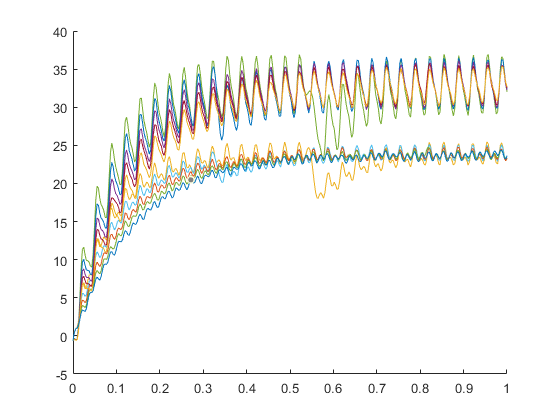

hold on
for k=1:length(L_floor)
    plot(times./(60*60*24*30), temps_floor(:, k), times./(60*60*24*30), temps_air(:, k));
end
hold off